# Getting Started with Hybrid Equations Toolbox

To finish the installation process, run the following command.

configure_toolbox

Autocomplete information is enabled for the Hybrid Equations Toolbox.
Tests skipped.

The Hybrid Equations Toolbox is ready to use.


## Mathematical Formulation of Hybrid Systems

A hybrid system is a dynamical system with continuous and discrete dynamics. We consider a hybrid system $\mathcal H$ on a state space $\mathbb{R}^n$ defined by the following objects:

- A set $C \subset \mathbb{R}^n$ called the *flow set*.

- A function $f : \mathbb{R}^n \to \mathbb{R}^n$ called the *flow map*.

- A set $D \subset \mathbb{R}^n$ called the *jump set*.

- A function $g : \mathbb{R}^n \to \mathbb{R}^n$ called the *jump map.*

We consider the simulation of hybrid systems $\mathcal  H = (C,f,D,g)$ written as


$$\mathcal H: \begin{cases}\dot x = f(x) & x \in C \\ x^+ = g(x) & x \in 
D \end{cases}$$


where $x \in \mathbb{R}^n$. The flow map $f$ defines the continuous dynamics on the flow set $C$, while the jump map $g$ defines the discrete dynamics on the jump set $D$. These objects are referred to as the *data* of the hybrid system $\mathcal H$ and are denoted$\mathcal H = (C,f,D,g)$. 

## Structure of the Hybrid Equations Toolbox

- matlab: contains the source code for the MATLAB portion of the toolbox. 

- simulink: contains the source code for the Simulink portion of the toolbox.

- Examples: contains code for examples that are described in <...>

- helpfiles: contains source code for LaTeX documentation and examples.

- docs: contains demos and getting started docuementation.

## Where to Find Help

- Documentation for the toolbox can be found in MATLAB Help (F1) at Supplemental Software > Hybrid Equations Toolbox.

- To see documentation for a particular component of the toolbox, execute  `help <name>` or `doc <name>` in the command line`,` where `<name>` is the name of a class, function or package (`help` prints a short description and `doc` opens the documentation page).

- To report a problem, request a feature, or ask for help, please [submit an issue](https://github.com/pnanez/HyEQ_Toolbox/issues/new) on toolbox's GitHub repository. 

- Simulink examples?

- A webinar introducing the HyEQ Toolbox v2.04 is available [here](http://www.mathworks.com/videos/hyeq-a-toolbox-for-simulation-of-hybrid-dynamical-systems-81992.html) (a free registration is required).

### Troubleshooting

**Problem**: When I call `HybridSystem.solve()`, the following error appears: "`Error using HyEQsolver. Too many input arguments.`" 

**Cause**: A previous version of the toolbox still installed. 

**Solution**: Uninstall the previous hybrid toolbox version by running `tbclean` inside the installation directory of the prior version.

**Problem**: I just uninstalled v2.40 and installed v3.0 of the Hybrid Equations Toolbox. Now <X> is not working.

**Cause**: ?? 

**Solution**: Restart MATLAB.

## MATLAB-based Hybrid Simulator

In this section, we will briefly demonstrate how to use the MATLAB-based portion of the hybrid toolbox to compute, analyze, and plot solutions to a hybrid system. We present these examples to introduction to what is possible and direct you to other pages in the documentation for detailed explanations for how to create, simulate, analyze and plot hybrid systems. For details about how to implement a hybrid system with the toolbox, see [How to Implement and Solve a Hybrid System](matlab:showdemo HybridSystem_demo). For more information about plotting hybrid solution, see [Creating plots with HybridPlotBuilder](matlab:showdemo HybridPlotBuilder_demo). 

### Creating and Solving a Hybrid System

In this example, we demonstrate a new approach to solving a hybrid system and plotting a solution. In `BouncingBallHybridSystem.m`, we define a hybrid system by creating a subclass of the `HybridSystem `class and implementing the `flowMap, jumpMap, flowSetIndicator, jumpSetIndicator` functions in order to specify $f, g, C$, and $D
$, respectively.

% Print the contents of the BouncingBall class.
type(which('hybrid.examples.BouncingBall'))

classdef BouncingBall < HybridSystem

    properties
        gravity = 9.8;
        bounce_coeff = 0.9;
    end

    methods 
        % To define the data of the system, we implement 
        % the abstract functions from HybridSystem.m

        function this = BouncingBall()
            this = this@HybridSystem(2);
        end

        function xdot = flowMap(this, x, t, j)
            xdot = [x(2); -this.gravity];
        end

        function xplus = jumpMap(this, x)
            xplus = [x(1); -this.bounce_coeff*x(2)];
        end
        
        function C = flowSetIndicator(this, x)
            C = x(1) >= 0 || x(2) >= 0;
        end

        function D = jumpSetIndicator(this, x)
            D = x(1) <= 0 && x(2) <= 0;
        end
    end

end


We then create an instance of the bouncing ball system:

sys_bb = hybrid.examples.BouncingBall();

A solution is then computed by calling the `solve` function on `system_bb` with the initial state and time spans as arguments. The `solve` function returns a `HybridSolution` object that contains information about the solution (use the properties `t, j,` and `x` to recover the standard output from `HyEQSolver`). 

x0 = [1; 0];
tspan = [0, 20];
jspan = [0, 30];
config = HybridSolverConfig('Refine', 32); % 'Refine' makes plots smoother.
sol_bb = sys_bb.solve(x0, tspan, jspan, config)

sol_bb =   HybridSolution with properties:

                      x0: [2×1 double]
                      xf: [2×1 double]
       termination_cause: J_REACHED_END_OF_JSPAN
                       t: [5439×1 double]
                       j: [5439×1 double]
                       x: [5439×2 double]
            flow_lengths: [30×1 double]
              jump_times: [30×1 double]
    shortest_flow_length: 0.0426
       total_flow_length: 8.2003
              jump_count: 30


### Plotting Hybrid Arcs

A collection of plotting functions are provided to plot `HybridSolution` objects.  

- `plotFlows`: plot a hybrid arc vs. ordinary time.

- `plotJumps`: plot a hybrid arc vs. discrete time`. `

- `plotHybrid`: plot a hybrid arc vs. ordinary and discrete time.

- `plotPhase`: plot the hybrid arc in phase space.

 Each function is called by passing a `HybridSolution` object to it. 

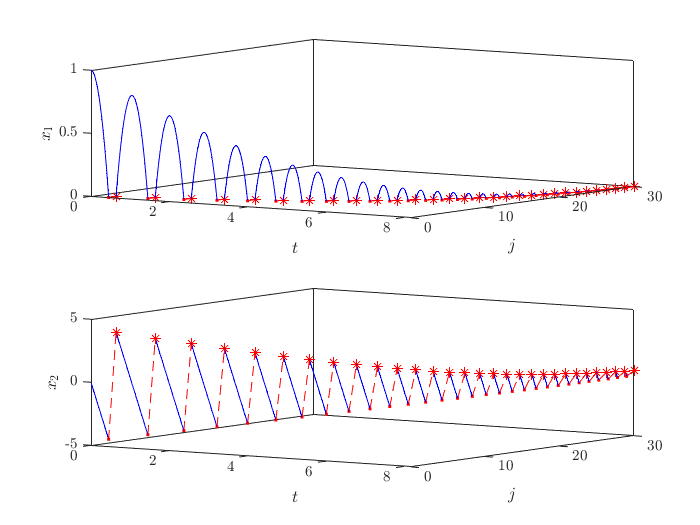

plotHybrid(sol_bb) 

To customize the appearance of plots, use the `HybridPlotBuilder` class, which has options for configuring lines, markers, text, etc. To generate plots, we create a `HybridPlotBuilder` object,  configure the plot via a series of function calls, and, finally, generate the plot with a call to one of the plotting functions (`plotFlows`, `plotJumps`, etc). An example is presented below. For a how-to guide to using HybridPlotBuilder, see [Creating plots with HybridPlotBuilder](matlab:showdemo HybridPlotBuilder_demo).

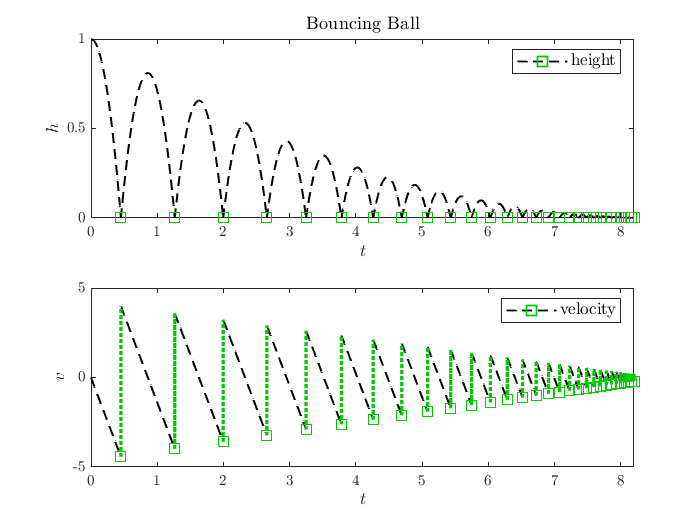

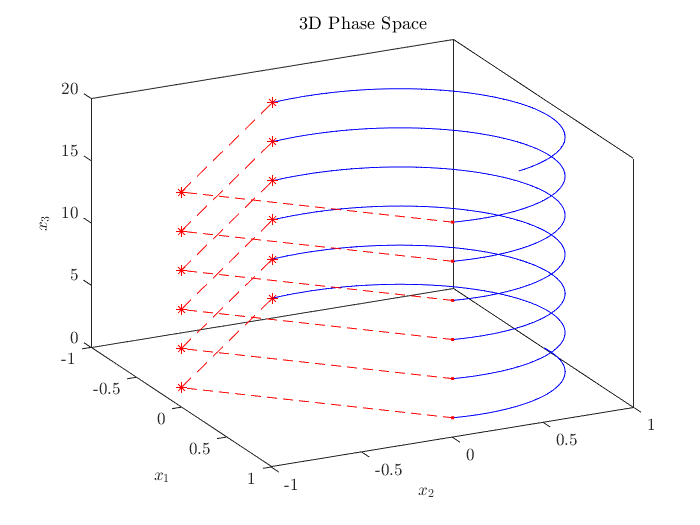

figure()
HybridPlotBuilder()... % Create an instance of HybridPlotBuilder
    .title("Bouncing Ball") ...
    .subplots('on')... % Place each component in a separate subplot
    .labels('$h$', '$v$') ...
    .legend('height', 'velocity')...
    .flowColor("black") ...
    .flowLineStyle("--") ...
    .flowLineWidth(1) ...
    .jumpColor([0, 0.8, 0]) ... % RGB color
    .jumpStartMarker("s") ... % Square marker
    .jumpStartMarkerSize(8) ...
    .jumpEndMarker("none") ...
    .jumpLineWidth(2) ...
    .jumpLineStyle(":") ...
    .plotFlows(sol_bb) % Generate plot

### Modifying Hybrid Arcs

Often, after calculating a solution to a hybrid system, we wish to manipulate the resulting data, such as evaluating a function along the solution, removing some of the components, or truncating the hybrid domain. A suite of functions to this end are included in the `HybridArc` class (`HybridSolution` is a subclass of `HybridArc`, so the solutions generated by `HybridSystem.solve` are `HybridArc` objects`).`

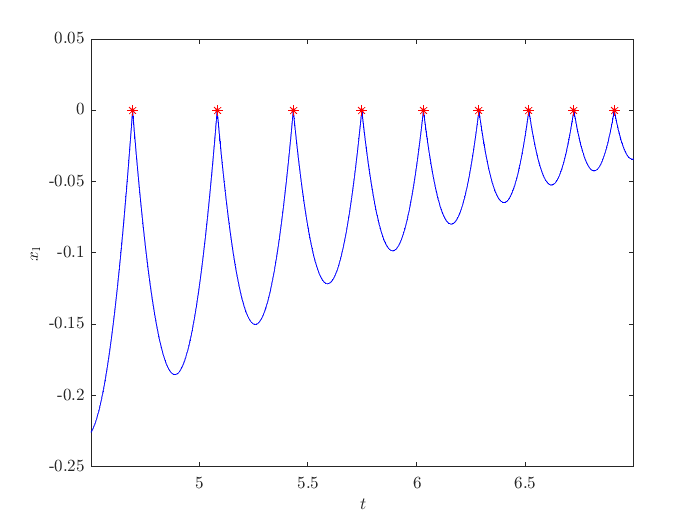

clf
hybrid_arc = sol_bb.slice(1);                 % Pick the 1st component.
hybrid_arc = hybrid_arc.transform(@(x) -x);   % Negate the value.
hybrid_arc = hybrid_arc.restrictT([4.5, 7]);  % Truncate to t-values between 4.5 and 7.
plotFlows(hybrid_arc)

### Asserting Conditions on Hybrid Systems

When implementing a hybrid system, it is helpful to verify whether $C$ and $D$ contain particular points. This is accomplished with four functions in `HybridSystem: assertInC`, `assertInD`, `assertNotInC,` and `assertNotInD`. 

x_ball_above_ground = [1; 0];
sys_bb.assertInC(x_ball_above_ground);
sys_bb.assertNotInD(x_ball_above_ground);

In addition to checking that a given point is in the desired set, the functions `assertInC`, `assertInD` also check that the flow or jump map, respectively, can be evaluated at the point and produces a vector with the correct dimensions.

If an assertion fails, as in following code, then an error is thrown and execution is terminated:

try
    sys_bb.assertInD(x_ball_above_ground) % This fails.
catch e 
    fprintf(2,'Error: %s',e.message);
end

Error: Point was expected to be inside D but was not.

### Multiple Interlinked Hybrid Systems

The Hybrid Equations Toolbox also supports defining multiple subsystems that are joined together to create a composite hybrid system. 

To implement a composite hybrid system, a `CompositeHybridSystem` object is constructed from one or more `HybridSubsytem` objects. `HybridSubsystems` can either be implemented by writing a subclass of `HybridSubsystem` or using one of the existing subclasses in the `hybrid.subsystems` package. 

In the following example we create a composite system that consists of three subsystems: a linear time-invariant plant, a controller, and a zero-order hold. Each is a subclass of `HybridSubsystem`. As before, this only intended as an introduction for what is possible. For details about about creating and using composite systems, see [Create and Simulate Multiple Interlinked Hybrid Systems](matlab:showdemo CompositeHybridSystem_demo).

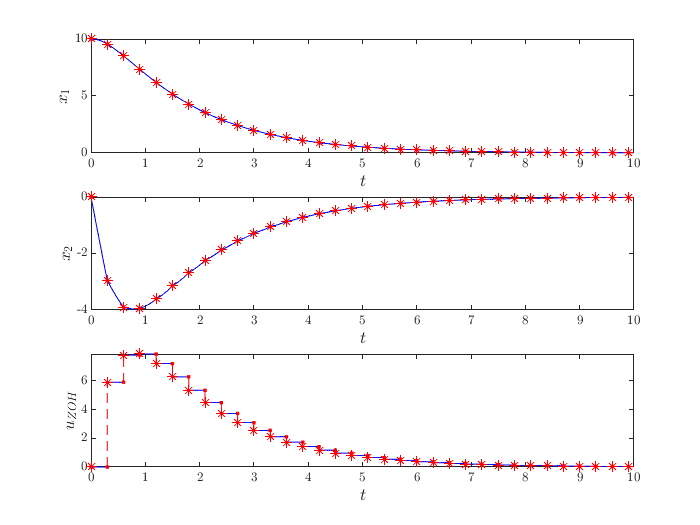

% Create LTV plant
A_c = [0, 1; -1, 0];
B_c = [0; 1];
plant_zoh = hybrid.subsystems.LinearContinuousSubsystem(A_c, B_c);

% Create a linear feedback controller.
K = [0, -2];
controller_zoh = hybrid.subsystems.MemorylessSubsystem(2, 1, @(x, u) K*u);

% Create a zero-order hold subsystem. 
zoh_dim = plant_zoh.input_dimension;
sample_time = 0.3;
zoh = hybrid.subsystems.ZeroOrderHold(zoh_dim, sample_time);

% Create the composite system
sys_zoh = CompositeHybridSystem(plant_zoh, controller_zoh, zoh);

% Set the connections between the subsystems
sys_zoh.setInput(plant_zoh, @(~, ~, y_zoh) y_zoh);
sys_zoh.setInput(controller_zoh, @(y_plant, ~, ~) y_plant);
sys_zoh.setInput(zoh, @(~, y_controller, ~) y_controller);

% Create the initial state for each subsystem
x0_plant = [10; 0];
x0_controller = []; % Controller is memoryless, so state is empty.
x0_zoh = [0; zoh.sample_time];
x0_composite = {x0_plant, x0_controller, x0_zoh}; 

% Compute a solution.
sol_zoh = sys_zoh.solve(x0_composite, [0, 10], [0, 100]);

% Plot the solution
HybridPlotBuilder().subplots('on')...
    .slice(1:3).labels('$x_1$', '$x_2$', '$u_{ZOH}$')...
    .plotFlows(sol_zoh)

## Simulink-based Hybrid Simulator

<TO-DO>

## New Features in Version 3.0

Hybrid Equations Toolbox v3.0 introduces the use of object-oriented programming to improve the Hybrid Equations Toolbox. A selection of the new features is listed here and is followed by examples.

- **Encapsulated Definitions of Hybrid Systems.** A hybrid system can be defined in a single file by creating a subclass of the `HybridSystem` class. This allows the creation of multiple hybrid systems without name conflicts and enables the definition of system parameters without using global variables.

- **Interconnected Hybrid Systems.** It is now possible to independently define the composition of several interconnected hybrid systems with inputs and outputs, such as a plant and a controller. Solutions to the composite system can be simulated like any other system.

- **More Informative Solutions.** The new `HybridSolution` class includes additional useful information about solutions such as the duration of each interval of flow and the reason the solution terminated. Methods are provided for modifying solution objects by, e.g., applying a map to transform the state values or truncating the time span. 

- **Improved Progress Updates.** While computing solutions, a progress bar displays the percent completed and the current hybrid time. The progress updates during both flows and at jumps (in v2.04, progress updates were only printed to the command line at jumps).

- **Improved Plotting.** Plotting hybrid solutions is easier and allows more control over the appearance of plots. New features include (1) easy control of the marker and line styles for flows and jumps, (2) ability to hide portions of hybrid solutions from plots using a filter (useful for plotting different modes in different styles), (3) support for legends, (4) automatic creation of subplots for solutions with multiple components, and (5) ability to set default plot settings. Plotting methods are up to 200x faster than in v2.04.

- **Fixed Bugs.** Fixed a bug in in v2.04 where `HyEQsolver` would sometimes produce solutions that flowed outside $C$.

- **Validation and error reporting.** New error checking catches programming mistakes earlier. Over 300 automated tests verify the correctness of the toolbox's code.

- **Code Autocompletion.** The Hybrid Equations Toolbox supports MATLAB's auto-completion (introduced to the MATLAB code editor in R2021b).

- **Backward Compatibility. **All code that works in Toolbox version 2.04 is expected to work in v3.0 without modification. Version 3.0 is comptatible with MATLAB versions back to R2014b.

## **Changes Between Builds**

Please send any questions, suggestions or defects to Paul Wintz at [pwintz@ucsc.edu](matlab: web('mailto:pwintz@ucsc.edu')).

### 3.0.0.22 $\to$ 3.0.0.??

Improved documentation.

### 3.0.0.20 $\to$ 3.0.0.22

(Built November 19, 2021)

- `HybridSubsystem`: Added support for defining separate output functions for flows and jumps.

- Added functions to `HybridSystem` and `HybridSubsystem `to check that the data for a given hybrid (sub)system return values of the correct sizes and to assert that particular points are or are not inside $C$ or $D$. See `checkFunctions`, `assertInC`, `assertInD`, `assertNotInC`, and `assertNotInD.`

- Changed installation process so that autocomplete is disabled until `configure_toolbox` is run (a prompt is shown in `GettingStarted`). Previously, users on older versions of MATLAB had to run `configure_toolbox` to disable autocompletions or else see errors in the command line.

- Added functions for transforming `HybridSolution` objects. See `HybridSolution.transform`, `HybridSolution.slice`, `HybridSolution.restrictT`, and `HybridSolution.restrictJ.`

- Reorganized files.

### 3.0.0.13 $\to$ 3.0.0.20

(Built November 4, 2021)

Changes to `HybridPlotBuilder:`

- Labels and titles can now be given as cell arrays.

- Replaced `HybridPlotBuilder.plot()` function with `HybridPlotBuilder().plotPhase() `for plotting the trajectory of state values through state space. (Previously, `plot` automatically selected whether to make `plotFlows` and `plotPhase` style plot based on the dimension of the state space. This is no longer supported.)

- Added ability to set multiple colors in `HybridPlotBuilder` so that if auto-subplots are off, each component is drawn in a different color. Modified `HybridPlotBuilder.configurePlots()` to take a function handle with two arguments, instead of one. The (new) first argument is the axes to configure and the second is the component index (previously the only argument).

- Renamed `HybridPlotBuilder.autoSubplots` method to `HybridPlotBuilder.subplots` and changed the default value to `'off'`. For a `HybridSolution` object `sol`, calling `plotFlows(sol)`, `plotJumps(sol)`, or `plotHybrid(sol)` (without prefixing "`HybridPlotBuilder.")` automatically selects whether automatic subplots are on or off based on the dimension of the system.

Changes to `HybridSolverConfig:`

- Added option to set flow or jump priority in `HybridSolverConfig` as `config.priority('flow') and config.priority('jump'), respectively`.

- Removed `HybridSolverConfig.flowPriority` and `HybridSolverConfig.jumpPriority` methods. Use `HybridSolverConfig.priority('flow')` and `HybridSolverConfig.priority('jump')` instead

Changes to `HybridSubsystemSolution` (previously  `HybridSolutionWithInput`)`:`

- Added output values `y`.

Miscellaneous Changes

- Added autocomplete information for `HyEQsolver`, `Hybridsystem`, `CompositeHybridSystem`, `HybridSolution`, `HybridPlotBuilder`, `HybridSubsystem, HybridSolverConfig, `and `HybridSystemBuilder.build` (Try it in the MATLAB 2021b code editor!)

- Extended compatibility back to MATLAB 2014b.

- Removed `HybridSolution.fromLegacy(t, j, x, f, g, C, D, tspan, jspan)` function. Use `HybridSolution(t, j, x, C, D, tspan, jspan)` instead.

### 3.0.0.11 $\to$ 3.0.0.13

In `HybridPlotBuilder:`

- It is now possible to chain calls to `HybridPlotBuilder` functions, such as `HybridPlotBuilder().plotflows(sol1).plotflows(sol2)`. This means it is often unnecessary to save the `HybridPlotBuilder` object to a variable.

- Changed how adding legends works in `HybridPlotBuilder`.

- Fixed how the label and title are selected when automatic subplots is off. 

- Fix x-axis limits when using subplots. (Previously, the x limits did not updated when subsequent plots were added after the first)

- Renamed `configureSubplots` in `HybridPlotBuilder` to `configurePlots`. The given function is now called in 2D and 3D phase plots, and when automatic subplots are off, as well as the other plotting functions.

- Add default configuration to `HybridPlotBuilder` (Still a work in progress!).

In `CompositeHybridSystem` (Previously `CompoundHybridSystem`)

- Renamed `CompoundHybridSystem` to `CompositeHybridSystem.`

- subsystems can now be referenced by ordinal number, object reference, or by name (if given in constructor) when setting inputs and referencing subsystem solutions. 

- The output functions for `HybridSubsystems` can now be a function of `x`, `u`, `t`, and/or `j`, instead of only `x`. 

- Input and output functions must be given as anonymous functions and unused arguments should be marked as ignored by replacing the argument name with a tilde (~). 

- Input functions can omit arguments from the end of their argument list any arguments (i.e., unneeded output values from other subsystems). 

- The way the dimensions and output of `HybridSubsystem` subclasses are set has changed.

Miscellaneous changes

- Automated toolbox tests can be run by calling `hybrid.tests.run()`.

### 3.0.0.6 $\to$ 3.0.0.11

Name changes (see the `rename_variables.sh` script for automatic renaming for all occurances)

- Renamed all method names to use camelCase naming. That is, we renamed `flow_map` to `flowMap, jump_map` to `jumpMap`, `plotflows` to `plotFlows` etc. (Functions from v2.04 are left unchanged for backward compatibility)

- `ControlledHybridSystem` to `HybridSubsystem`

- `ControlledHybridSolution` to `HybridSolutionWithInput`

- `control_dimension` to `input_dimension` in `HybridSubsystem`

- `plotHybridArc` to `plotHybrid` in `HybridPlotBuilder`.

Changes in `HybridSystem`

- A `HybridSystem` object can now be created from function handles `@f, @g, @C, @D` simply by calling `sys = HybridSystem(@f, @g, @C, @D).`

- Add checks if the "`this"` argument is missing from `flowMap(this, x, t, j), jumpMap(this, x, t, j),` etc.

- In `solve(), a`dd default values `tspan=[0, 10] `and `jspan=[0, 10].`

Changes in `HyEQsolver`

- Rewrote solver algorithm 

- Fixed all known bugs!

- Fix: close progress bar regardless of how `HyEQsolver` exits.

Changes in `CompoundHybridSystem` and `HybridSubsystem` (previously `ControlledHybridSystem)`

- Add output function to `HybridSubsystem` class.

- Rewrote `CompoundHybridSystem` to support an arbitrary number of subsystems.

- Add `PairHybridSystem` to support faster computations and cleaner code for systems with only two subsystems.

- Renamed `HybridSubsystem` property from "`control_dimension`" to "`input_dimension`"

Changes in `HybridPlotBuilder`

- Fix: legends now correctly placed in subplots.

- Add padding to top and bottom of plots made with `plotFlows`, and `plotJumps.`

- Add `configureSubplots` function to allow the full range of plot customization offered by MATLAB.

- Add `autoSubplots` function to set whether subplots are automatically created for each state component.

- Fixed linking between 3D subplots generated by `plotHybrid` so they rotate and pan together.

- Improved plotting speed by up to ~200x.

- Add `addLegendEntry` function to include plots in the legend that were not created by `HybridPlotBuilder`. 

Miscellaneous changes

- Add ability to set ode solver options such as "AbsTol" and "MaxStep" via arguments to the `HybridSolverConfig` constructor, as well as "silent" to disable progress bar.

- In `HybridSolution,` removed the values of f, g, C, and D along solutions. Instead, they can be computed as need using `HybridSystem.generateFGCD()`. To compute the values of an arbitrary vector-valued function along a solution, use `HybridSolution.evaluateFunction()`.

- Move several functions from `HybridUtils` the `hybrid.internal` package.

- Make `hybrid.interal.jumpTimes` returns the values of $j$ and indices immediately before a jump, instead of immediately after.

- Expanded documentation and unit tests.